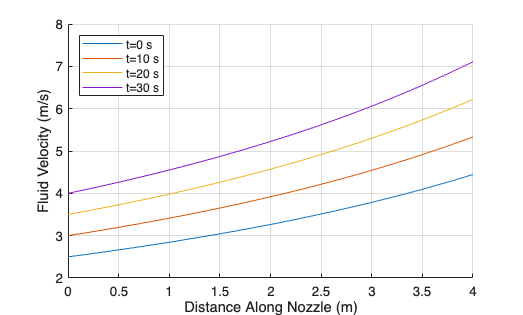

figure(1);
clf();
hold on;
figure(2)
clf();
hold on;
xx = linspace(0,4,100);
for tt = [0 10 20 30]
    vv = (10+0.2*tt)*pi./(pi/4*(4-0.25*xx).^2);
    figure(1)
    label = sprintf("t=%.0f s",tt);
    plot(xx,vv, "DisplayName", label)
    figure(2)
    aa = 0.5./(4-0.25*xx).^2 + 0.5*(24+0.5*tt).^2./(2-0.125*xx).^5;
    plot(xx,aa, "DisplayName", label )
end
figure(1)
xlabel('Distance Along Nozzle (m)')
ylabel('Fluid Velocity (m/s)')
legend('Location','northwest')
grid('on')

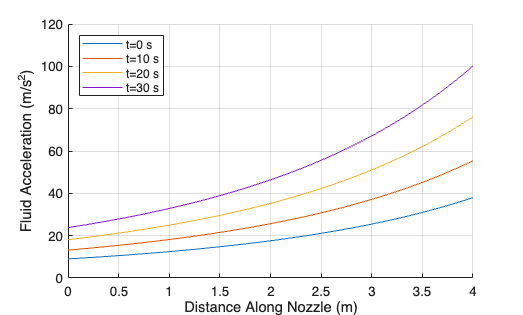

figure(2)
xlabel('Distance Along Nozzle (m)')
ylabel('Fluid Acceleration (m/s^2)')
legend('Location','northwest')
grid('on')